## Rotational controller Ideas

One idea is to develop a detached automatic skew controller that evaluates an optimal skew angle based on a cost function :

$I_{v\;}$= $\left(\begin{array}{ccc}
\textrm{Ixx} & \textrm{Ixy} & 0\\
\textrm{Iyx} & \textrm{Iyy} & 0\\
0 & 0 & \textrm{Izz}
\end{array}\right)$


$$I_v \left(\Lambda \right)=I_{v_0 } +\left(\begin{array}{ccc}
\sum_{k=1}^{\tilde{k} } m_k \;\left(\sin^2 \left(\Lambda \right)x_{k_0 \;}^2 +\cos^2 \left(\Lambda \right)y_{k_0 }^2 \right) & -\sum_{k=1}^{\tilde{k} } m_k \left(y_{k_0 }^2 +x_{k_0 }^2 \right)\sin \left(\Lambda \right)\cos \left(\Lambda \right) & 0\\
-\sum_{k=1}^{\tilde{k} } m_k \;\left(y_{k_0 }^2 +x_{k_0 }^2 \right)\sin \left(\Lambda \right)\cos \left(\Lambda \right) & \sum_{k=1}^{\tilde{k} } m_k \;\left(\cos^2 \left(\Lambda \right)x_{k_0 \;}^2 +\sin^2 \left(\Lambda \right)y_{k_0 }^2 \right) & 0\\
0 & 0 & 0
\end{array}\right)$$



$$M_c =\left\lbrack \begin{array}{cccc}
0 & -\cos \left(\Lambda \right){\mathrm{bk}}_1  & 0 & \cos \left(\Lambda \right){\mathrm{bk}}_1 \\
{\mathrm{bk}}_1  & -\sin \left(\Lambda \right){\mathrm{bk}}_1  & -{\mathrm{bk}}_1  & \sin \left(\Lambda \right){\mathrm{bk}}_1 \\
k_2  & {-k}_2  & k_2  & -k_2 
\end{array}\right\rbrack \omega^{2\;} +\left\lbrack \begin{array}{cccc}
-{\sin \left(\Lambda \right)l}_a {\;k}_{a\;} v^2  & {\sin \left(\Lambda \right)l}_a {\;k}_a \;v^2  & 0 & 0\\
-{\cos \left(\Lambda \right)l}_a {\;k}_a \;v^2  & {\cos \left(\Lambda \right)l}_a {\;k}_a \;v^2  & l_e {\;k}_e \;v^2  & 0\\
0 & 0 & 0 & l_r {\;k}_r \;v^2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\delta_{a_l } \\
\delta_{a_r } \\
\delta_e \\
\delta_r 
\end{array}\right\rbrack$$


What we have estimated experimentally are effectiveness values which relate to angular acceleration as follows:


$$\Delta \alpha =G*\Delta u\;\Longrightarrow G=\frac{\Delta \alpha }{\Delta u}$$


at the same time from euler we know that. Assuming linear thrust curve.


$$\begin{array}{l}
M=I_v \;\alpha \;\\
\frac{M_2 -M_1 }{I_{v_2 } -I_{v_1 } }=\alpha_2 -\alpha_1 \Longrightarrow \Delta \alpha =\frac{\Delta M}{I_v }=\frac{\sum b_k \;k_k {\;\omega }_k \;f\left(\Lambda \right)}{I_v }
\end{array}$$



$$\frac{\Delta M}{\Delta \alpha }$$


syms Ixx Ixy Iyy Izz
I(Ixx,Ixy,Iyy,Izz) = [Ixx Ixy 0; Ixy Iyy 0; 0 0 Izz];
I_inv(Ixx,Ixy,Iyy,Izz) = I^-1;


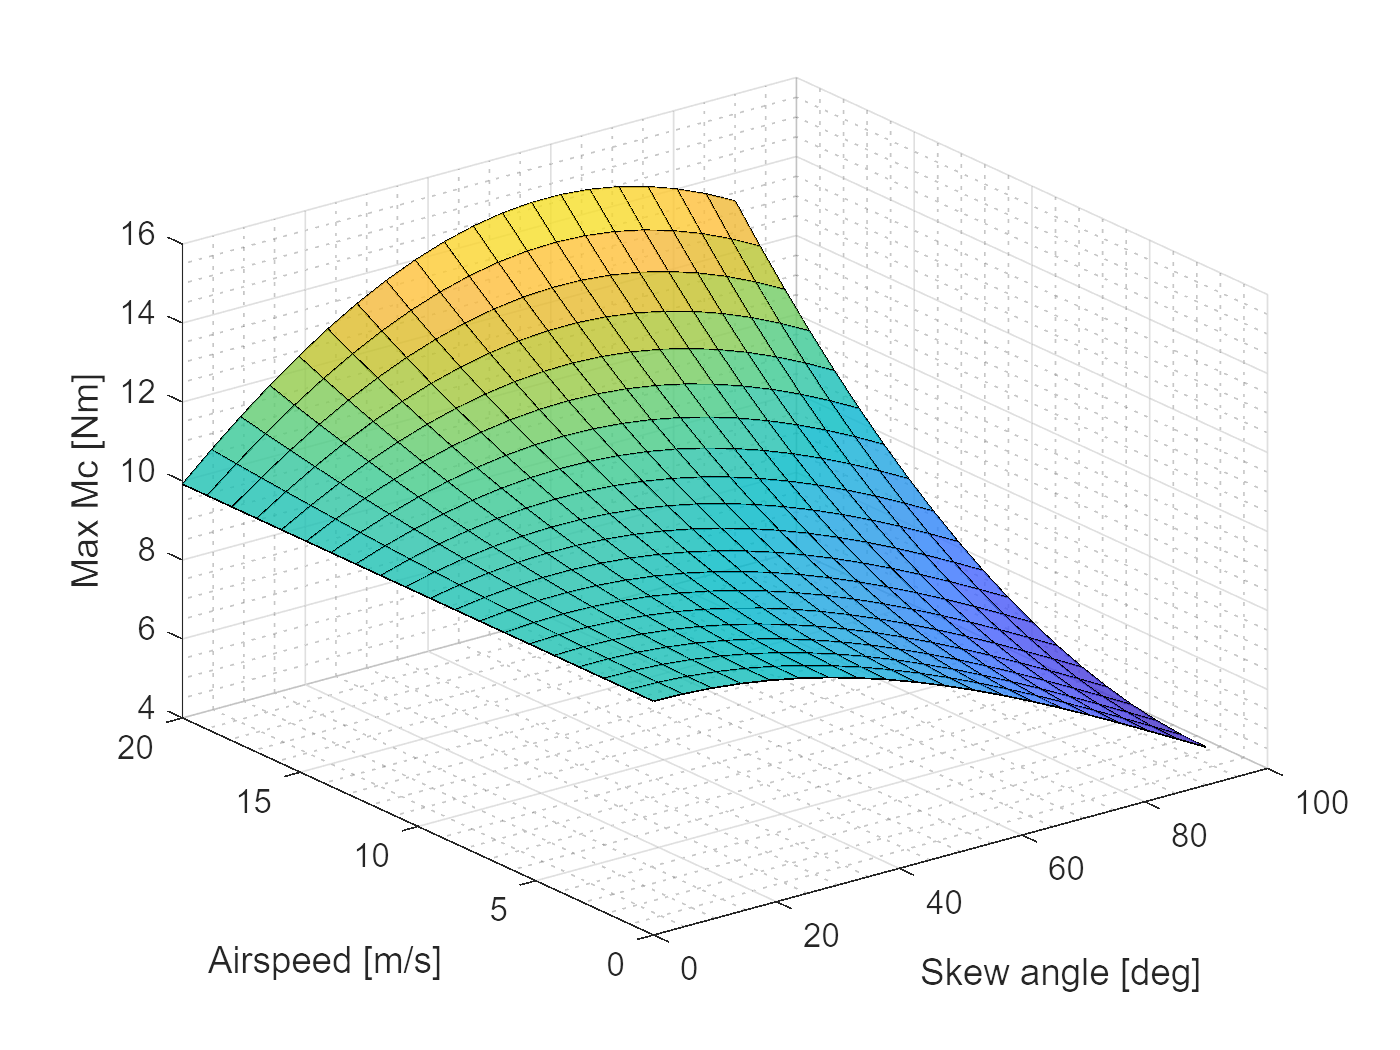

lambda_q = linspace(0,pi()/2,20);
v_q = linspace (0,20,20);
mass = 3.5;
cl_max = 1.3;
lift = 0.5 * 1.225 * 1.3 * 1.56 * 0.235 * (sin(lambda_q) * v_q)^2;
Thrust = max(mass*9.81 - lift,0);
u_lim_mot = [0 9600];
u_lim_as  = [-9600 9600]
b = 0.345;
la = 0.75;
le = 0.9;
lr = 0.9;
k1 = 16/9600;
ka =k1/(12^2)/150;
ke = k1/(12^2)/50;
kr = k1/(12^2)/50;
[L,V] = meshgrid(lambda_q,v_q);

% M1 = abs([b*k1,-sin(lambda_q)*b*k1,-b*k1,sin(lambda_q)*b*k1;
%     0,-cos(lambda_q)*b*k1,0,cos(lambda_q)*b*k1;
%     0,0,0,0]);
% 
% M2 = abs([-cos(lambda_q)*la*ka*v_q^2,cos(lambda_q)*la*ka*v_q^2,0,0;
%     -sin(lambda_q)*la*ka*v_q^2,sin(lambda_q)*la*ka*v_q^2,le*ke*v_q^2,0;
%     0,0,0,lr*kr*v_q^2]);

roll = 2*9600*la*ka*V.^2*sin(L)+2*b*k1*4600+2*b*k1*4600*cos(L);
pitch = (cos(L)*b*k1)*2*4600+2*sin(L)*la*ka*V.^2*9600+le*ke*V.^2*9600;

figure(1)
clf
surf(rad2deg(L),V,roll,'FaceAlpha',0.8)
grid on
grid minor
hold on 
%plot3( lambda_q(roll(:,1)==max(roll)),v_q(roll(:,1)==max(roll)),max(roll))
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Max Mc [Nm]')



lambda_ref = [0,pi/4,pi/2];
Ixx_ref = [2.049e-2,2.394e-2, 2.862e-2];
Ixy_ref = [2.593e-4,4.258e-3,1.113e-4];
Iyx_ref = [2.593e-4,4.258e-3,1.113e-4];
Iyy_ref = [2.065e-1,2.028e-1, 1.979e-1];
Ixz_ref = [8.238e-3,8.079e-3,7.977e-3];%*10^-1;%e-3
Iyz_ref = [-2.422e-4,-2.005e-4,-2.7692e-5];
Izx_ref = [8.238e-3,8.079e-3,7.977e-3];%*10^-1;%e-3
Izy_ref = [-2.422e-4,-2.005e-4,-2.7692e-5];
Izz_ref = [2.164e-1,2.161e-1,2.158e-1];

Ixx_q = interp1(lambda_ref,Ixx_ref,lambda_q);
Ixy_q = interp1(lambda_ref,Ixy_ref,lambda_q);
Iyy_q = interp1(lambda_ref,Iyy_ref,lambda_q);
Izz_q = interp1(lambda_ref,Izz_ref,lambda_q);


At the moment the WLS outerloop takes an acceleration set point and output deltas in phi, theta, T and Tbx for a given skew angle. As an indirect result also airspeed is controlled.

However, assume we can model the control capabilities of the drone. Then we can determine which skew angle maximises control authority for any given airspeed.


$${\;I}_v \left(\Lambda \right)\;\alpha_c =M_c \left(v,\Lambda \right)$$



$$\alpha_c ={\;I}_v {\left(\Lambda \right)}^{-1\;} M_c \left(v,\Lambda \right)$$



$$\max_{\Lambda } \;\left\lbrack \begin{array}{c}
\gamma_{\phi } \\
\gamma_{\theta } \\
\gamma_{\psi } 
\end{array}\right\rbrack \frac{M_c \left(\Lambda ,v\right)}{I_v \left(\Lambda \right)}$$
          

 vpa(I_inv(Ixx_ref(1),Ixy_ref(1),Iyy_ref(1),Izz_ref(1))*ones(3,1)*b*k1,3)